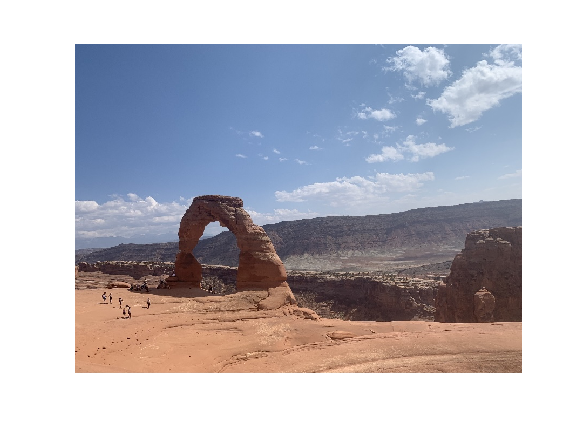

img = imread("rock.png");
figure;
hFig = imshow(img);

info = imfinfo("rock.png");
disp(['image width:' num2str(info.Width) '; image height:' num2str(info.Height) '; color depth:' num2str(info.BitDepth)]);

image width:828; image height:611; color depth:24


class(img)

ans = 'uint8'

size(img)

ans =    611   828     3


tmpImg=uint8(zeros(size(img)));
tmpImg(:,:,1)=img(:,:,1)

tmpImg = 611×828×3 uint8 array
tmpImg(:,:,1) =

    71    72    71    69    71    72    70    69    68    70    72    73    73    73    72    72    69    73    74    73    73    71    70    72    70    73    72    73    72    71    75    73    70    72    74    74    74    75    74    72    71    74    74    72    73    76    75    72    74    74    75    75    75    75    74    74    74    74    75    75    75    74    74    74    75    76    76    76    76    75    76    77    76    77    77    76    76    76    77    78    77    78    78    77    78    78    78    76    77    76    77    77    78    78    77    76    75    78    79    78    77    78    79    79    78    78    78    80    82    82    81    79    80    80    80    80    80    80    80    81    79    80    80    79    80    81    81    80    82    81    81    82    82    82    82    81    82    84    84    82    82    84    84    81    82    83    83    84    83    84    84    84    83    85    85    84    85    84    

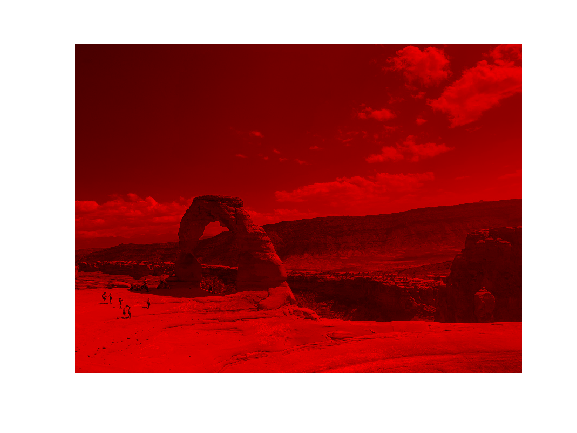

figure; imshow(tmpImg); % display the red channel


tmpImg=uint8(zeros(size(img)));
tmpImg(:,:,2)=img(:,:,2)

tmpImg = 611×828×3 uint8 array
tmpImg(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

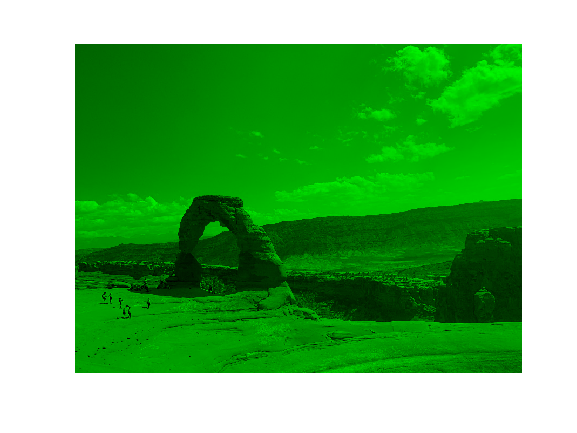

figure; imshow(tmpImg); % display the green channel


tmpImg=uint8(zeros(size(img)));
tmpImg(:,:,3)=img(:,:,3)

tmpImg = 611×828×3 uint8 array
tmpImg(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

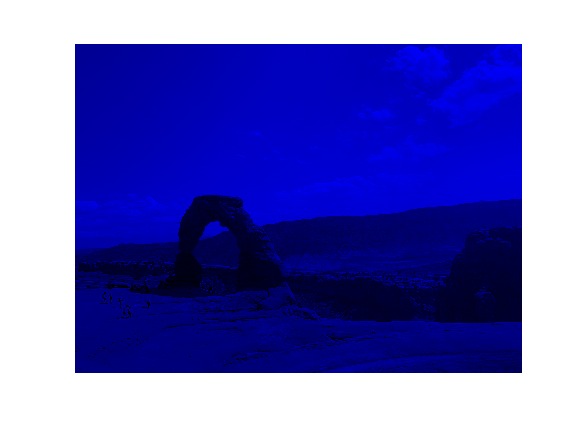

figure; imshow(tmpImg); % display the blue channel

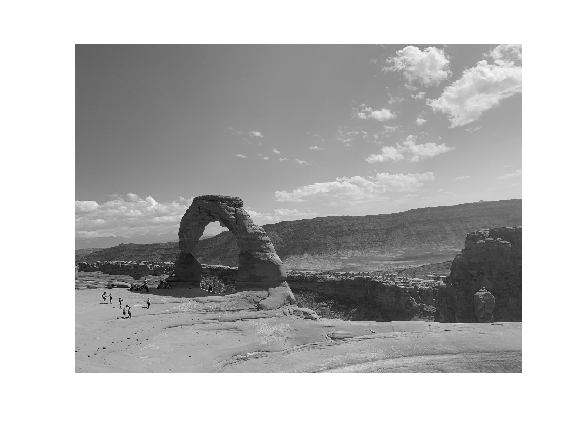

imgGray=rgb2gray(img);
imshow(imgGray);

frequency space

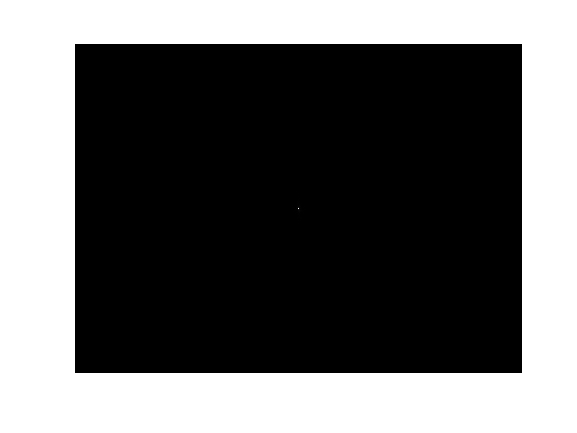

imgFFT=fft2(imgGray);
imagesc(abs(fftshift(imgFFT))); colormap gray; axis equal; axis off;

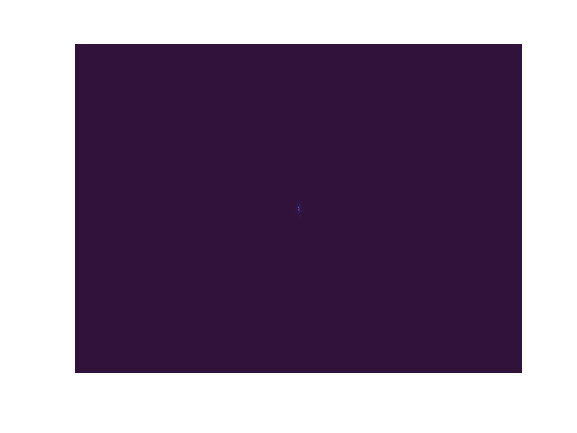

imagesc(abs(fftshift(imgFFT))); colormap turbo; axis equal; axis off;

frequency space in log scale

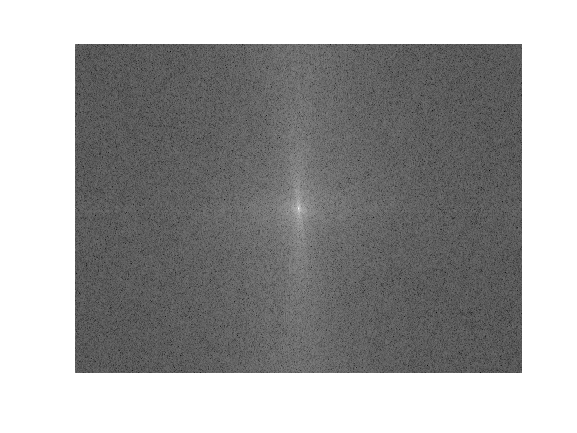

imgFFTb=abs(fftshift(imgFFT));
imagesc(log(abs(fftshift(imgFFT))+1)); colormap gray; axis equal; axis off;

spatial-frequency view

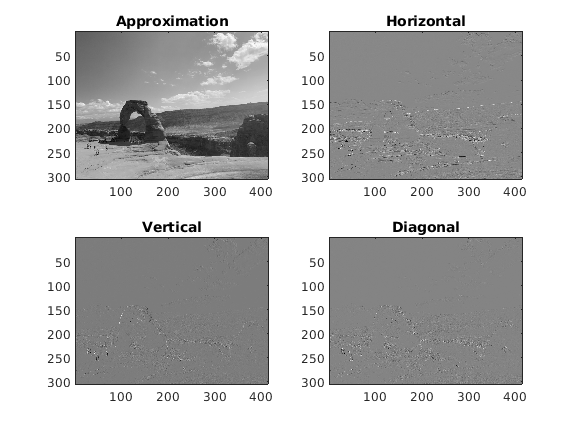

[LoD,HiD] = wfilters('haar', 'd');
[cA,cH,cV,cD] = dwt2(imgGray,LoD,HiD,'mode','symh');
figure;
subplot(2,2,1); imagesc(cA); colormap gray; title('Approximation')
subplot(2,2,2); imagesc(cH); colormap gray; title('Horizontal')
subplot(2,2,3); imagesc(cV); colormap gray; title('Vertical')
subplot(2,2,4); imagesc(cD); colormap gray; title('Diagonal')

Edge Features

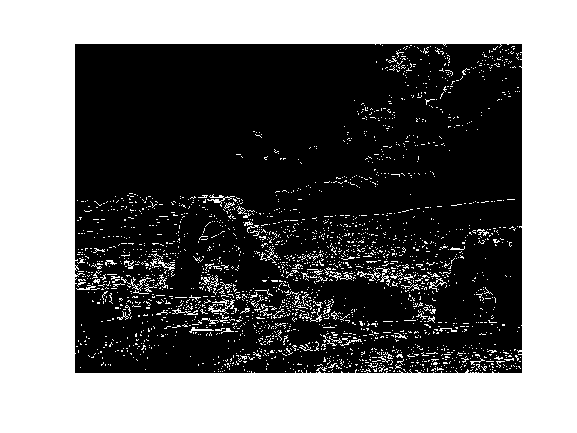

figure;
imagesc(edge(imgGray, 'sobel', 0.04)); colormap gray; axis equal; axis off;

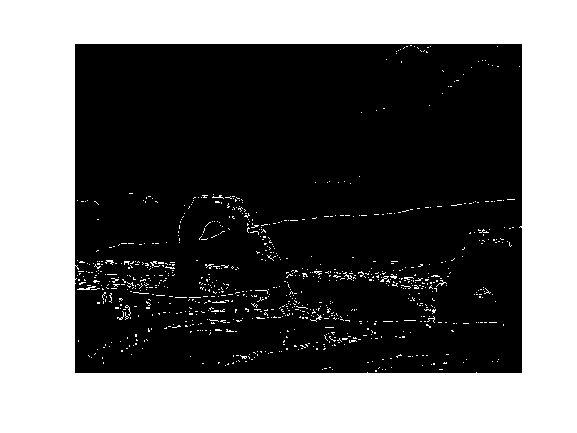

figure;
imagesc(edge(imgGray, 'sobel', 0.1)); colormap gray; axis equal; axis off;

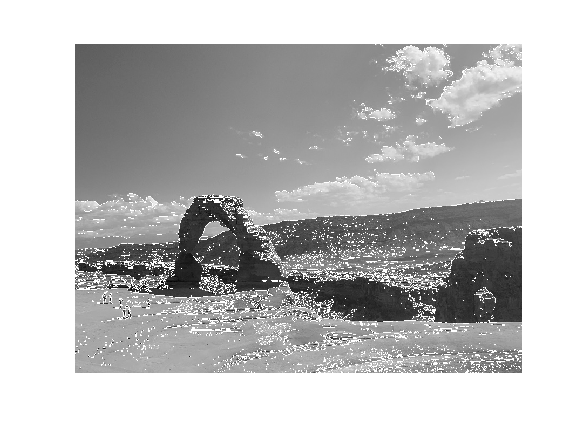

imagesc(uint8(double(imgGray)+255*double(edge(imgGray, 'sobel', 0.04)))); colormap gray; axis equal; axis off;

Image Histogram

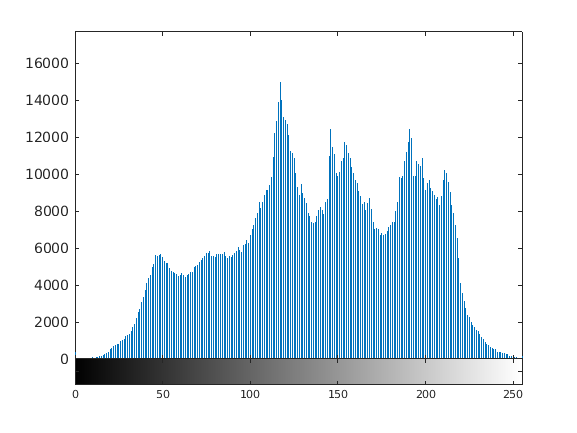

imhist(img);

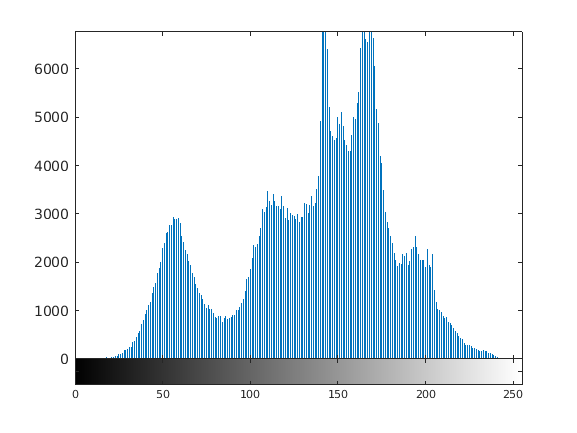

imhist(imgGray);